# LAB1 MATLAB Programming

Name(SID) and Name(SID)

## Introduction

This lab is to use MATLAB to compute numerical approximations to the CTFT integral, and explore amplitude modulation of Morse code messages. 

## Results and Analysis

### 4.2

#### (a)

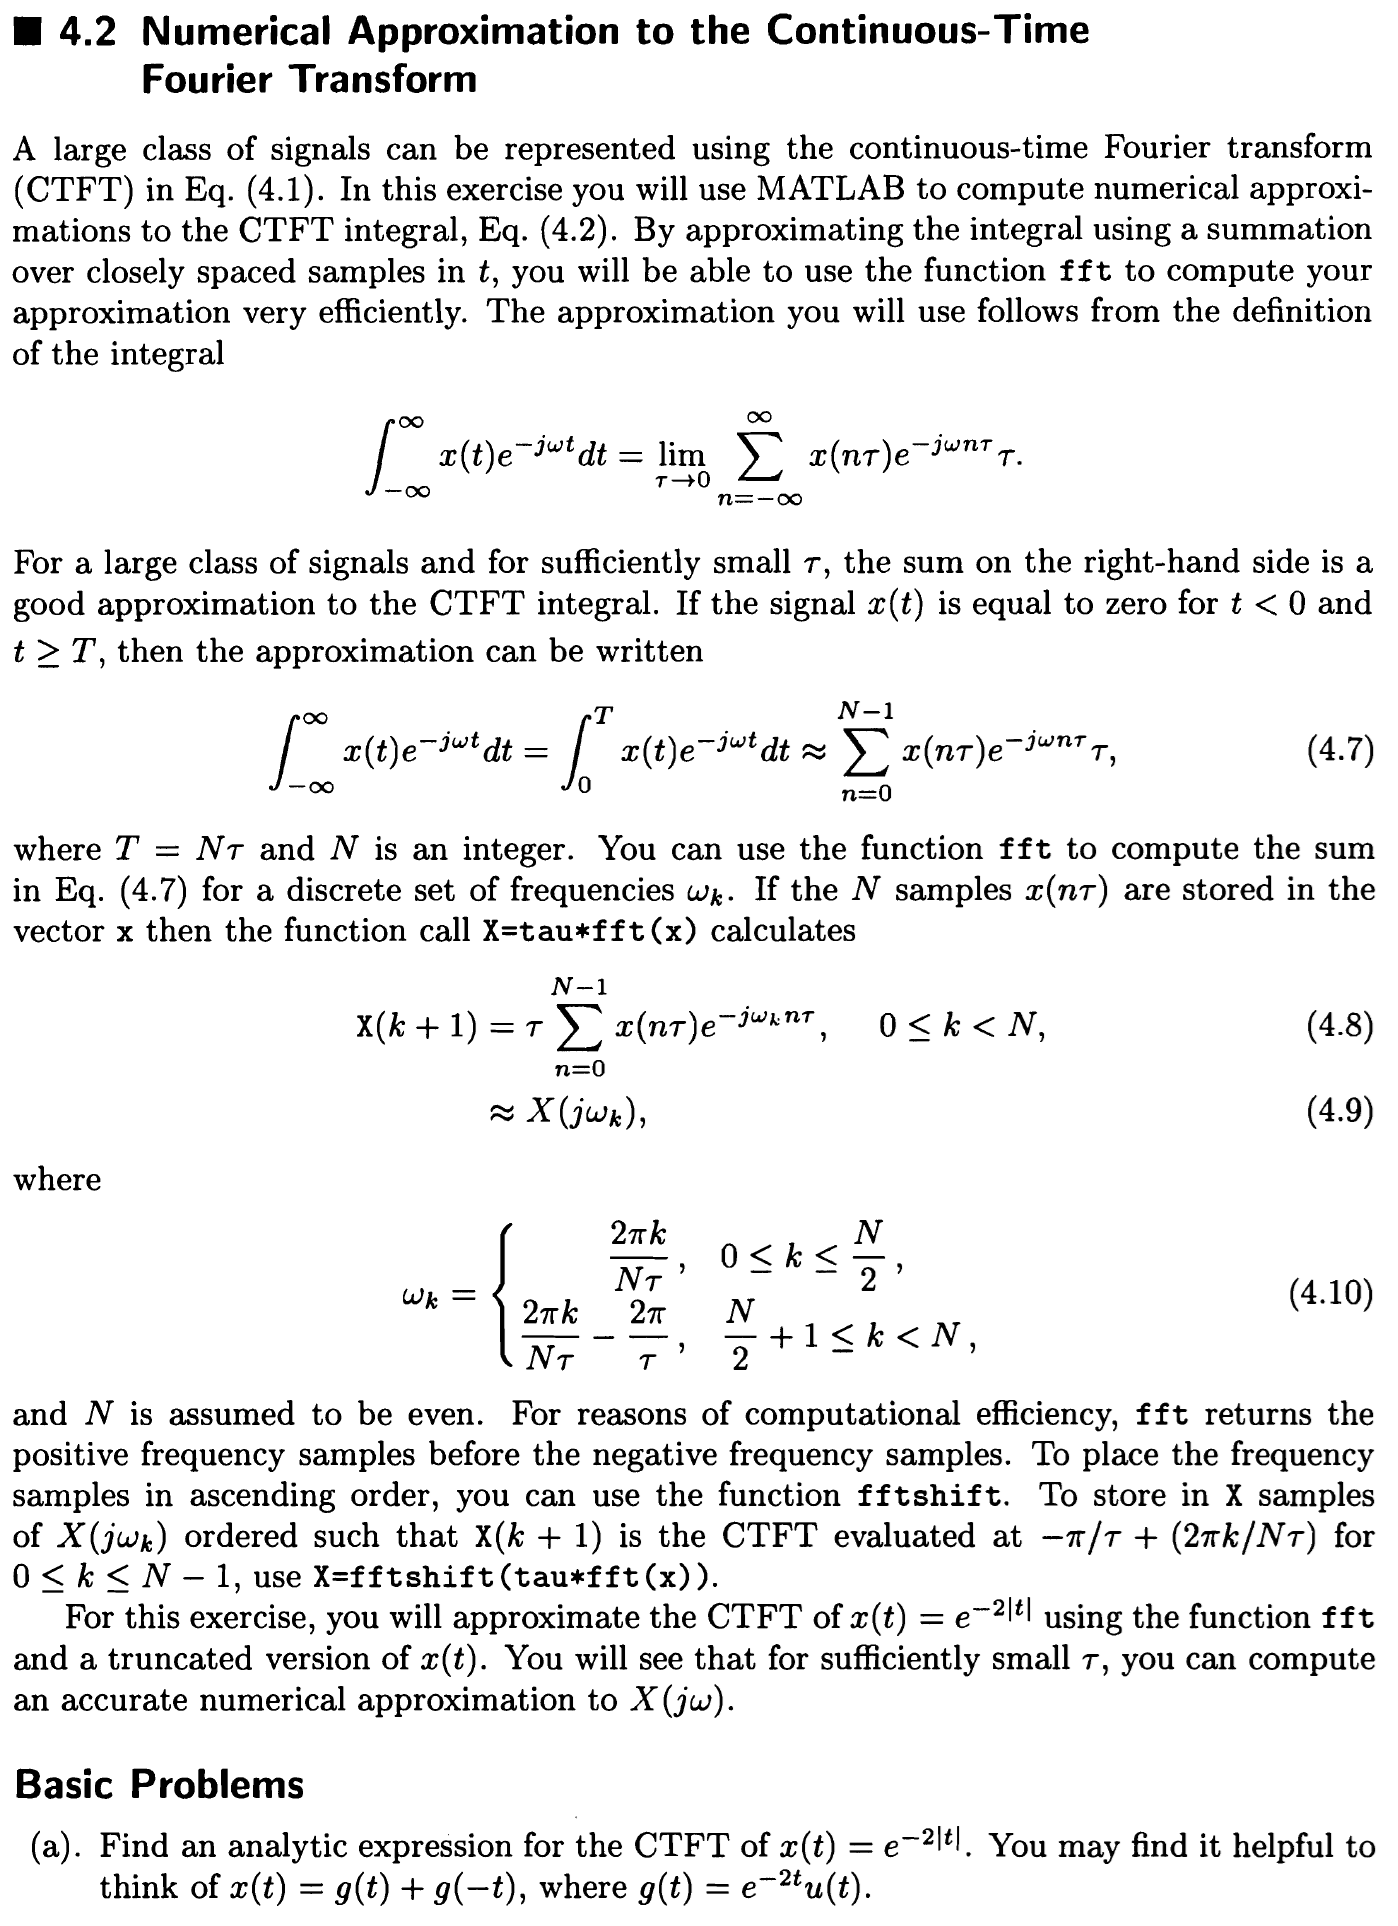

Initialize.

clear; clc; close all;

Calculate the analytic expression for $x(t)$.


$$\begin{array}{rcl}
G(j\omega) & = & F\{g(t)\} \\
& = & \frac{1}{2+j\omega}
\end{array}$$



$$\begin{array}{rcl}
X(j\omega) & = & F\{x(t)\} \\
& = & F\{g(t)+g(-t)\} \\
& = & F\{g(t)\}+F\{g(-t)\} \\
& = & G(j\omega)+G(-j\omega) \\
& = & \frac{1}{2+j\omega}+\frac{1}{2-j\omega}
\end{array}$$


#### (b)

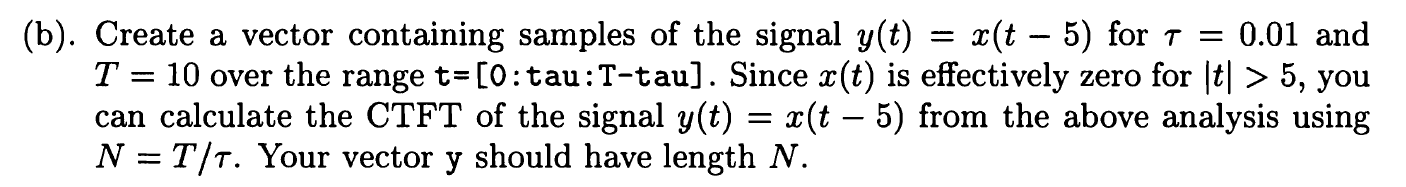

Create $\tau$, $T$, $N$, vector $t_x$, $x$, $t$, $y$.

tau = 0.01;
T = 10;
N = T/tau;
t = 0:tau:T-tau;
tx = t-5;
x = exp(-2*abs(tx));
y = x;

#### (c)

Calculate CTFT of $y(t)=x(t-5)$.

Y = fftshift(tau*fft(y));

#### (d)

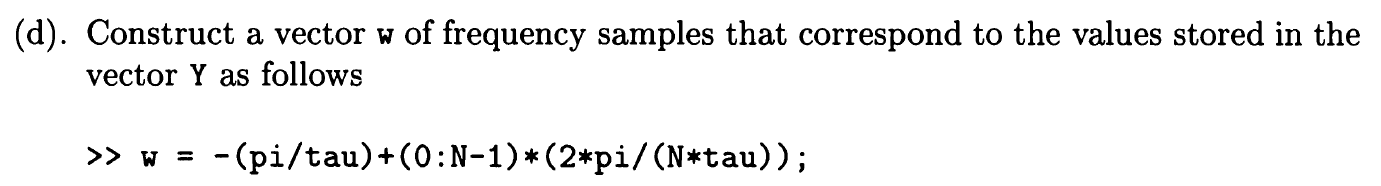

w = -(pi/tau)+(0:N-1)*(2*pi/(N*tau));

#### (e)

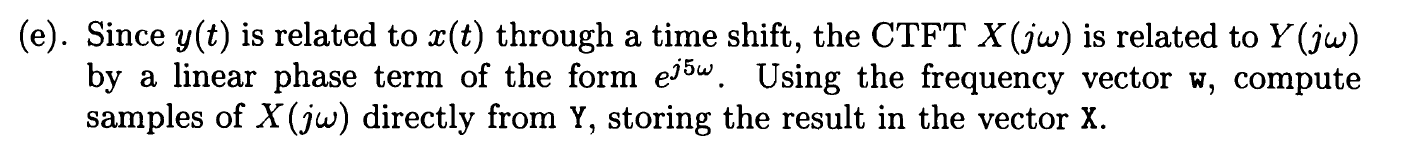

X = Y.*exp(1i*5*w);

#### (f)

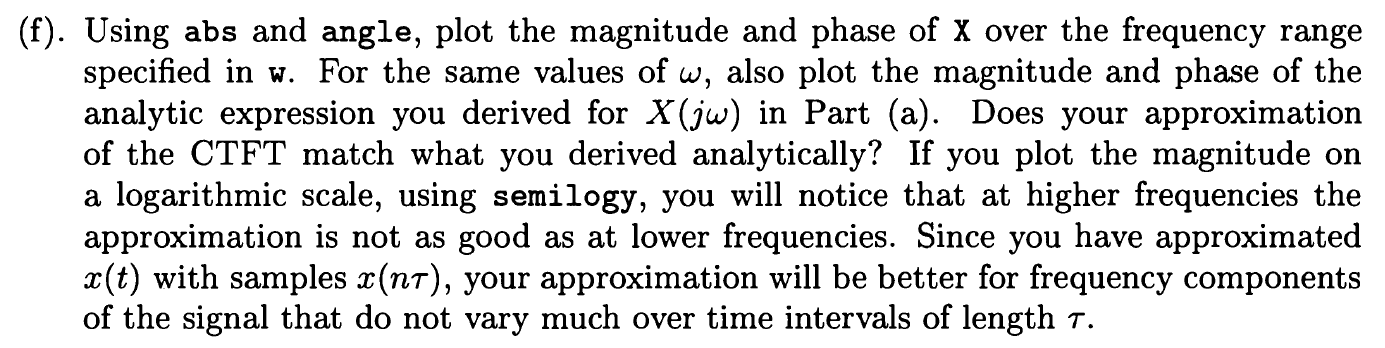

Calculate $X_{abs}$, $X_{angle}$.

Xabs = abs(X);
Xangle = angle(X);

Calculate $X_a$, $X_{abs_a}$, $X_{angle_a}$.

X_a = 1./(2+1i*w)+1./(2-1i*w);
Xabs_a = abs(X_a);
Xangle_a = angle(X_a);

Plot $X_{abs}$, $X_{abs_a}$, $X_{angle}$, $X_{angle_a}$.

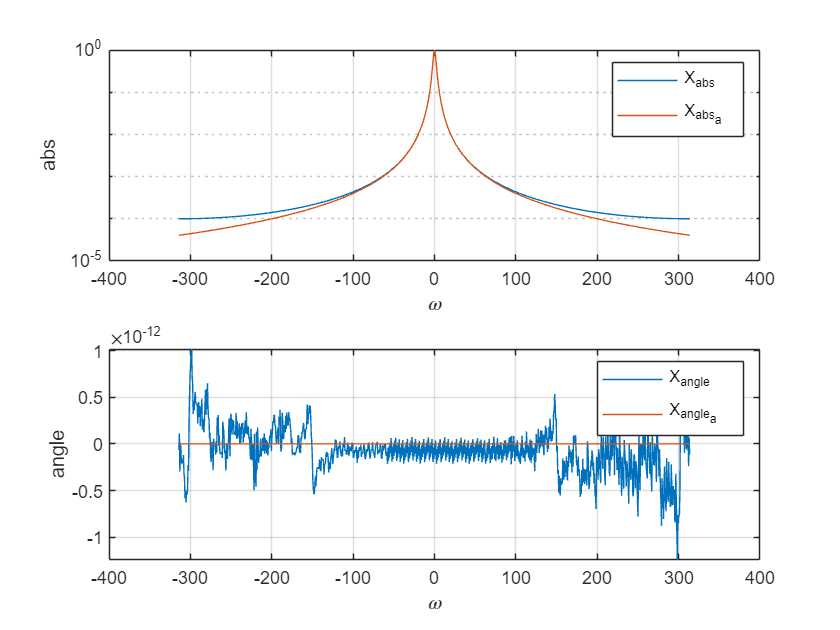

figure;
subplot(2,1,1);
semilogy(w,Xabs,w,Xabs_a);
legend("X_{abs}","X_{abs_a}");
grid on;
xlabel("\omega");
ylabel("abs");
subplot(2,1,2);
plot(w,Xangle,w,Xangle_a);
legend("X_{angle}","X_{angle_a}");
grid on;
xlabel("\omega");
ylabel("angle");

The approximation is totally matches when the frequency is low. But when the frequency is high, the approximation is not such accurate.

#### (g)

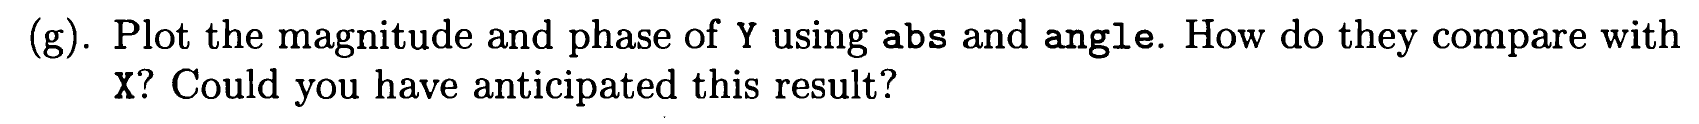

Calculate $Y_{abs}$, $Y_{angle}$.

Yabs = abs(Y);
Yangle = angle(Y);

Plot $X_{abs}$, $Y_{abs}$, $X_{angle}$, $Y_{angle}$.

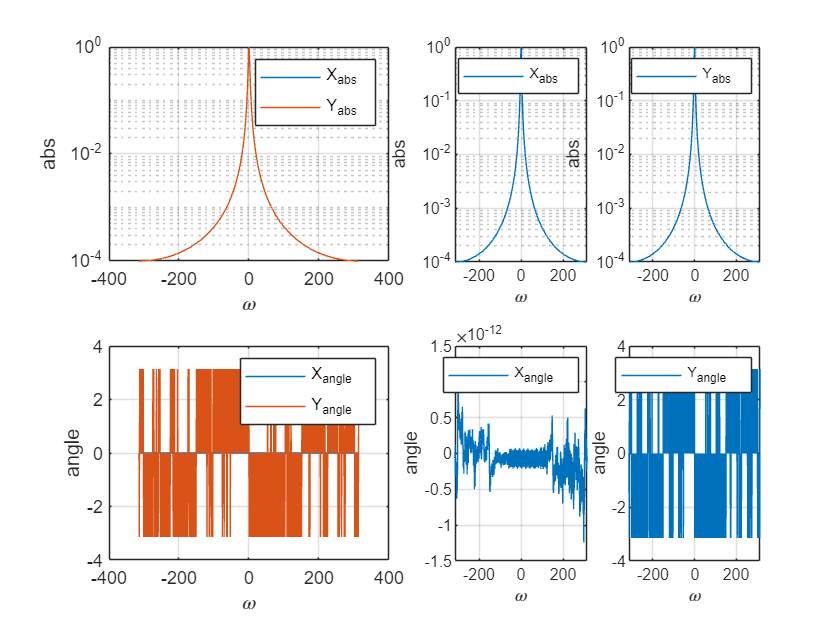

figure;
subplot(2,2,1);
semilogy(w,Xabs,w,Yabs);
legend("X_{abs}","Y_{abs}");
grid on;
xlabel("\omega");
ylabel("abs");
subplot(2,2,3);
plot(w,Xangle,w,Yangle);
legend("X_{angle}","Y_{angle}");
grid on;
xlabel("\omega");
ylabel("angle");
subplot(2,4,3);
semilogy(w,Xabs);
legend("X_{abs}");
grid on;
xlabel("\omega");
ylabel("abs");
subplot(2,4,4);
semilogy(w,Yabs);
legend("Y_{abs}");
grid on;
xlabel("\omega");
ylabel("abs");
subplot(2,4,7);
plot(w,Xangle);
legend("X_{angle}");
grid on;
xlabel("\omega");
ylabel("angle");
subplot(2,4,8);
plot(w,Yangle);
legend("Y_{angle}");
grid on;
xlabel("\omega");
ylabel("angle");

$X_{abs}$ and $Y_{abs}$ are the same while $X_{angle}$ and $Y_{angle}$ are very different. It's because the time shift only leads to phase shift in frequency domain, which is also mentioned in **(e)**.

### 4.6

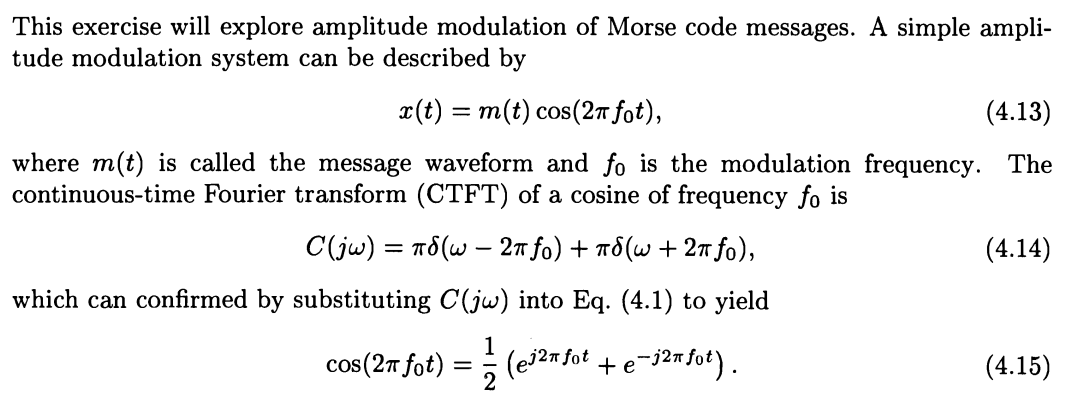

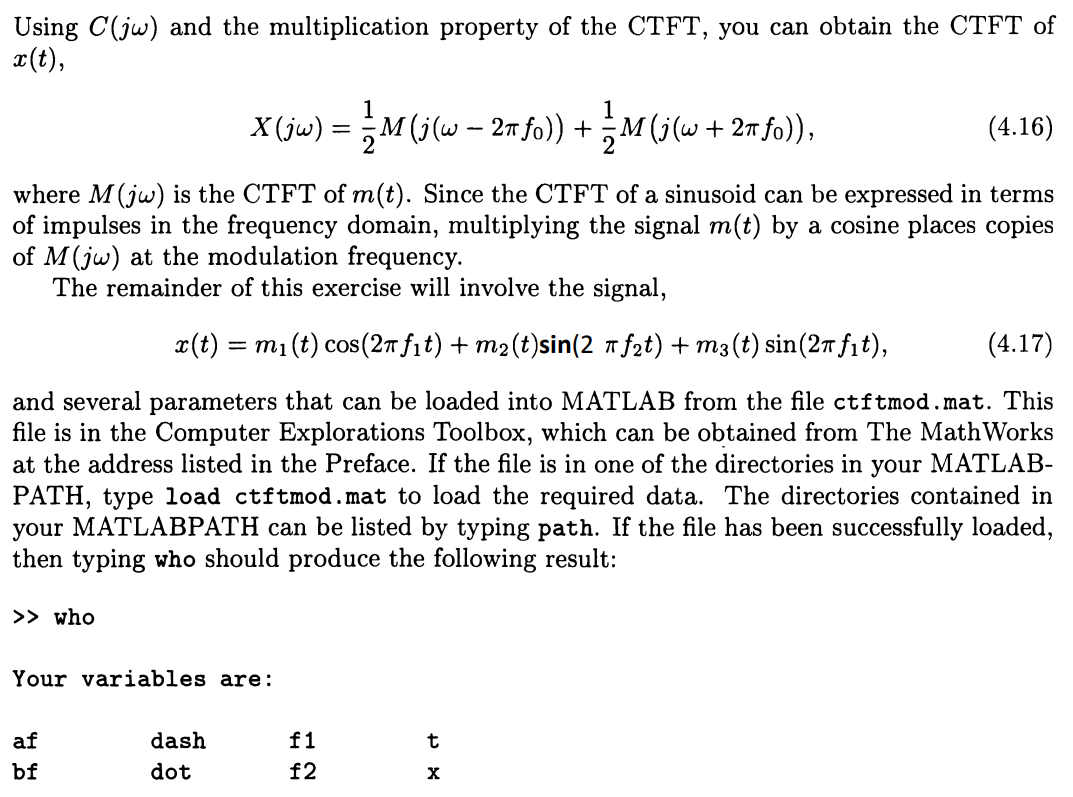

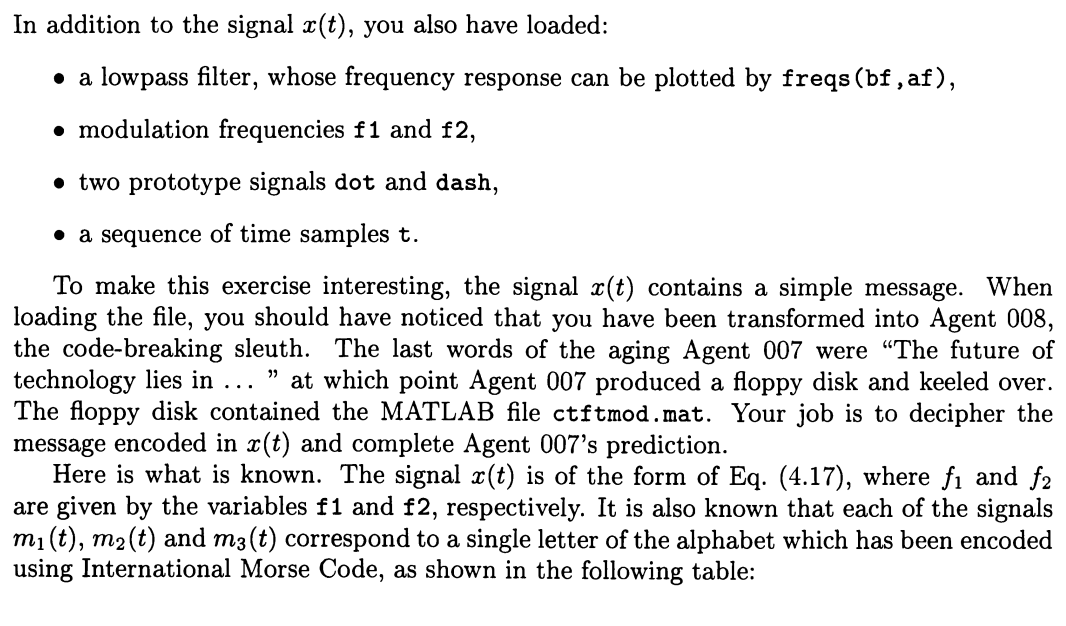

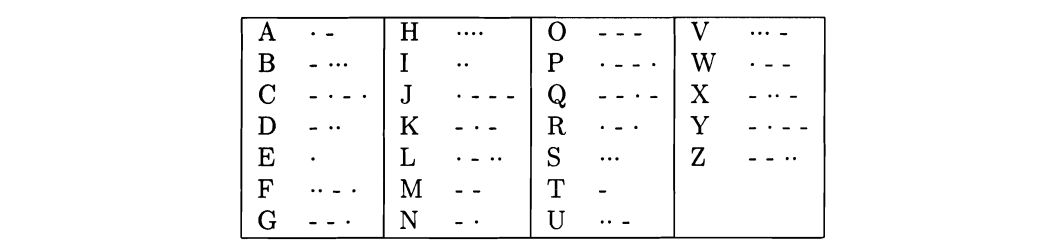

clc;clear;close all;

Load the file *ctftmod.mat*.

load ctftmod.mat

#### (a)

#### 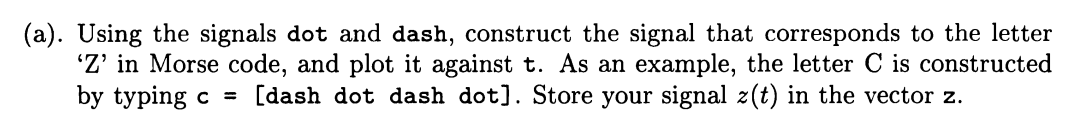

Create the signal of $Z$ in Morse code, plot it against $t$, and store the signal in the vector $z$.

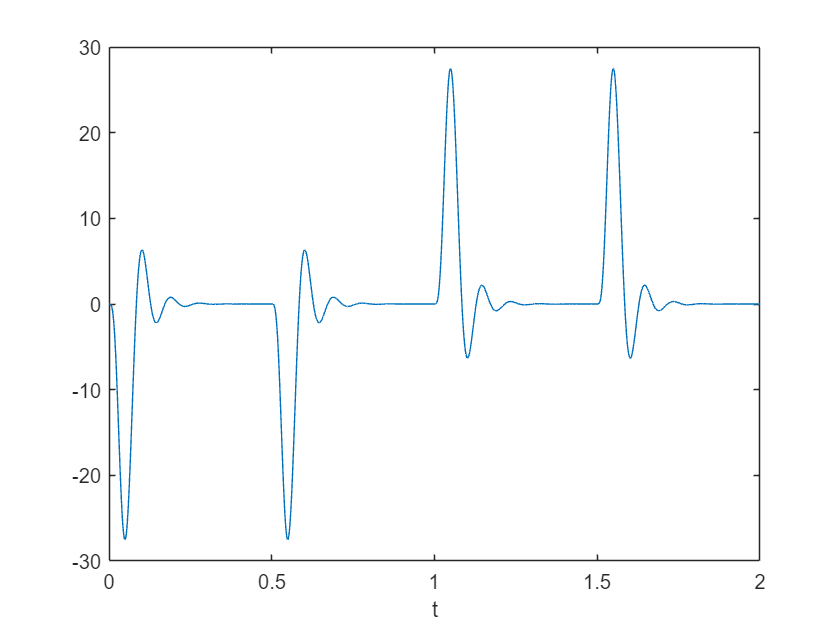

z = [dash dash dot dot];
figure;
plot(t,z);xlabel("t");

#### (b)

Plot the frequency response of the lowpass filter.

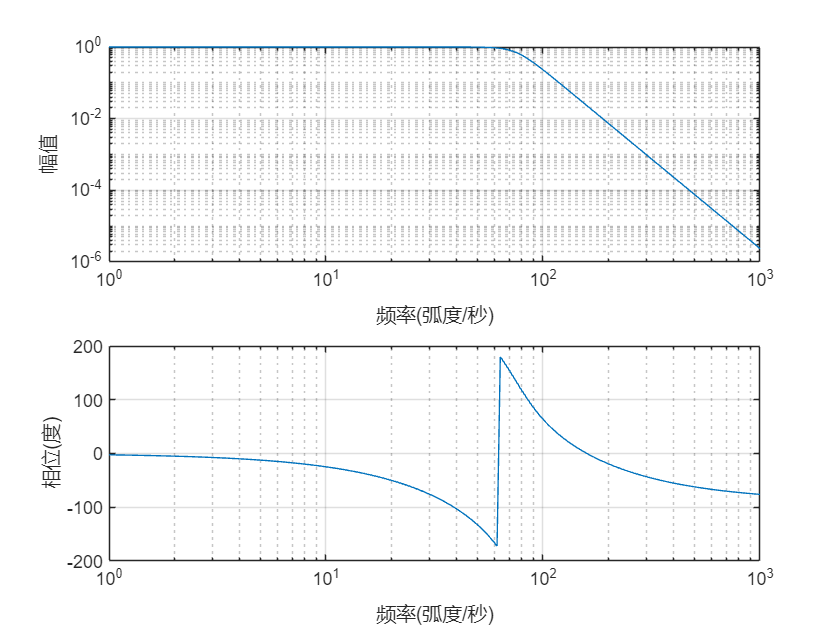

freqs(bf,af);

#### (c)

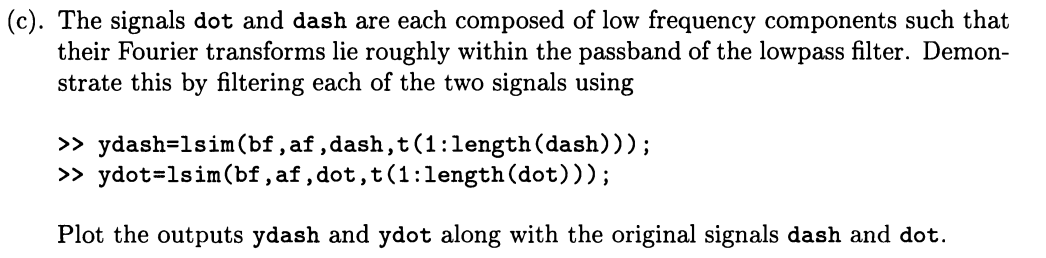

Plot the outputs $ydash$ and $ydot$ along with the original signals $dash$ and $dot$.

ydash = lsim(bf,af,dash,t(1:length(dash)));

'lsim' 需要以下项之一:
  Control System Toolbox
  System Identification Toolbox

ydot = lsim(bf,af,dot,t(1:length(dot)));
figure;
subplot(1,2,1);hold on;
plot(t(1:length(ydash)),ydash);
plot(t(1:length(dash)),dash);
legend('ydash','dash');
subplot(1,2,2);hold on;
plot(t(1:length(ydot)),ydot);
plot(t(1:length(dot)),dot);
legend('ydot','dot');

#### (d)

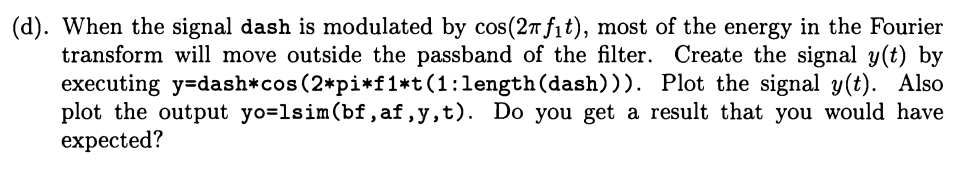

Create and plot the signal $y(t)$ and the output $yo$.

y = dash .* cos(2*pi*f1*t(1:length(dash)));
yo = lsim(bf,af,y,t(1:length(dash)));
figure;
subplot(1,2,1);
plot(t(1:length(y)),y);
subplot(1,2,2);
plot(t(1:length(yo)),yo);

The outpupt $yo$ fits the expected output.

#### (e)

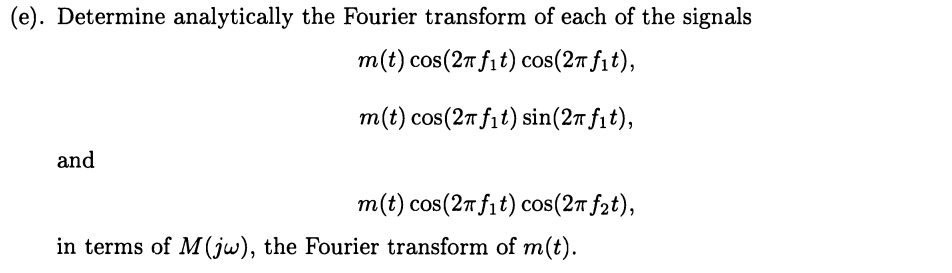

Assume $h_1(t) = m(t)cos(2\pi f_1t)cos(2\pi f_1t)$, $h_2(t) = m(t)cos(2\pi f_1t)sin(2\pi f_1t)$, $h_3(t) = m(t)cos(2\pi f_1t)cos(2\pi f_2t)$.

`The continuous-time Fourier transform (CTFT) of a cosine of frequency `$f_1$` is `$C_1(j\omega) = \pi\delta(\omega-2\pi f_1)+\pi\delta(\omega+2\pi f_1)$.

`Using `$C_1(jw)$` and the multiplication property of the CTFT to obtain `$H_1(j\omega)$.$$$
\begin{array}{rcl}
F\{m(t)cos(2\pi f_1t)\} & = & \frac{1}{2}M(j(\omega-2\pi f_1))+\frac{1}{2}M(j(\omega+2\pi f_1)) \\
F\{m(t)cos(2\pi f_1t)cos(2\pi f_1t)\} & = & \frac{1}{2}(\frac{1}{2}M(j(\omega-4\pi f_1))+\frac{1}{2}M(j\omega))+\frac{1}{2}(\frac{1}{2}M(j\omega)+\frac{1}{2}M(j(\omega+4\pi f_1))) \\
H_1(j\omega) & = & \frac{1}{4}M(j(\omega-4\pi f_1))+\frac{1}{2}M(j\omega)+\frac{1}{4}M(j(\omega+4\pi f_1))
\end{array}
$$$

`The continuous-time Fourier transform (CTFT) of a cosine of frequency `$f_1$` is `$S_1(j\omega) = \frac{\pi}{j}\delta(\omega-2\pi f_1)-\frac{\pi}{j}\delta(\omega+2\pi f_1)$.

`Using `$C_1(jw)$, $S_1(jw)$` and the multiplication property of the CTFT to obtain `$H_2(j\omega)$.


$$\begin{array}{rcl}
F\{m(t)cos(2\pi f_1t)\} & = & \frac{1}{2}M(j(\omega-2\pi f_1))+\frac{1}{2}M(j(\omega+2\pi f_1)) \\
F\{m(t)cos(2\pi f_1t)sin(2\pi f_1t)\} & = & \frac{1}{2j}(\frac{1}{2}M(j(\omega-4\pi f_1))+\frac{1}{2}M(j\omega))-\frac{1}{2j}(\frac{1}{2}M(j\omega)+\frac{1}{2}M(j(\omega+4\pi f_1))) \\
H_2(j\omega) & = & \frac{1}{4j}M(j(\omega-4\pi f_1))-\frac{1}{4j}M(j(\omega+4\pi f_1))
\end{array}$$


`The continuous-time Fourier transform (CTFT) of a cosine of frequency `$f_2$` is `$C_2(j\omega) = \pi\delta(\omega-2\pi f_1)+\pi\delta(\omega+2\pi f_1)$.

`Using `$C_1(jw)$, $C_2(jw)$` and the multiplication property of the CTFT to obtain `$H_3(j\omega)$.


$$\begin{array}{rcl}
F\{m(t)cos(2\pi f_1t)\} & = & \frac{1}{2}M(j(\omega-2\pi f_1))+\frac{1}{2}M(j(\omega+2\pi f_1)) \\
F\{m(t)cos(2\pi f_1t)cos(2\pi f_2t)\} & = & \frac{1}{2}(\frac{1}{2}M(j(\omega-2\pi f_1-2\pi f_2))+\frac{1}{2}M(j(\omega+2\pi f_1-2\pi f_2)))+\frac{1}{2}(\frac{1}{2}M(j(\omega-2\pi f_1+2\pi f_2))+\frac{1}{2}M(j(\omega+2\pi f_1+2\pi f_2))) \\
H_3(j\omega) & = & \frac{1}{4}M(j(\omega-2\pi f_1-2\pi f_2))+\frac{1}{4}M(j(\omega+2\pi f_1-2\pi f_2))+\frac{1}{4}M(j(\omega-2\pi f_1+2\pi f_2))+\frac{1}{4}M(j(\omega+2\pi f_1+2\pi f_2))
\end{array}$$


#### (f)

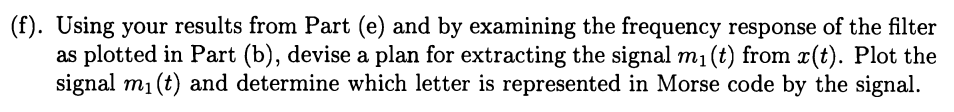

Decode $m_1(t)$ from $x(t)$, and plot them against $t$.

x1 = x .* cos(2*pi*f1*t(1:length(x)));
m1 = lsim(bf,af,x1,t(1:length(x1)));
figure;
plot(t(1:length(m1)),m1);xlabel('t');ylabel('m_1');

According to Morse code, $m_1$ means letter $D$.

#### (g)

Decode $m_2(t)$ and $m_3(t)$ from $x(t)$, and plot them against $t$.

x2 = x .* sin(2*pi*f2*t(1:length(x)));
m2 = lsim(bf,af,x2,t(1:length(x2)));
x3 = x .* sin(2*pi*f1*t(1:length(x)));
m3 = lsim(bf,af,x3,t(1:length(x3)));
figure;
subplot(2,1,1);
plot(t(1:length(m2)),m2);xlabel('t');ylabel('m_2');
subplot(2,1,2);
plot(t(1:length(m3)),m3);xlabel('t');ylabel('m_3');

According to Morse code, $m_2$ means letter $H$.

According to Morse code, $m_3$ means letter $P$.

## Expeience

`Through Matlab work, I have a preliminary understanding of Matlab simulation tools in the signal and system of the application of the discipline. I'm more famililar with the usage of `approximation method of CTFT to solve problem`. And I have a better understanding of the CTFT and the differences between `approximation method `and analytical method. I learn how to use MATLAB to compute numerical approximations to the CTFT integral, and explore amplitude modulation of Morse code messages. `

欧阳安男（12211831）：

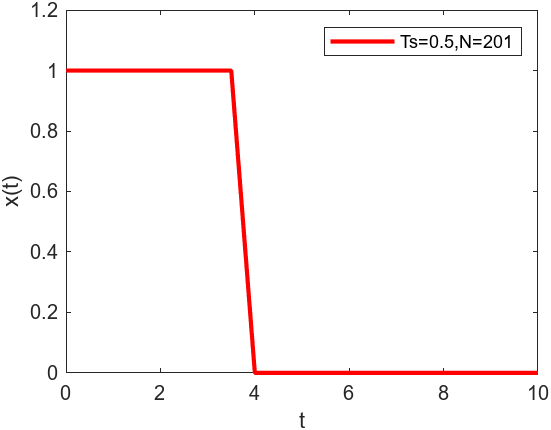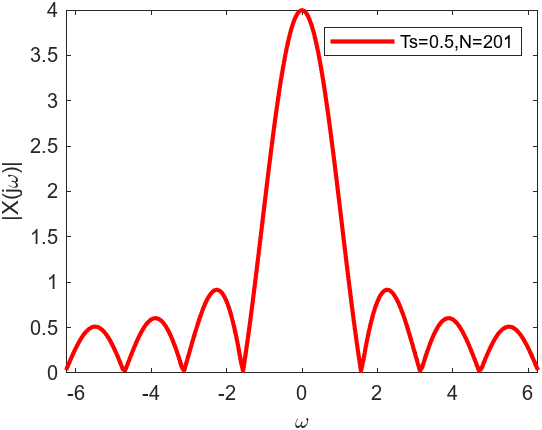

涂峻绫（12213010）：

## Score

涂峻绫（100） 欧阳安男（100）